# 4. Semesterproject

## Declaring variables for the two systems

### Cart

clc; clear;
syms x          % [m]       position 
syms x_d        % [m/s]     velocity
syms x_dd       % [m/s^2]   acceleration
syms T_c        % [N]       tension force
syms F_c        % [N]       external force

m_c = 0.5       % [Kg]      mass of cart

m_c = 0.5000

b_c = 5         % [N/(m/s)] damping coefficient, cart

b_c = 5

g = 9.82        %           gravity coefficient

g = 9.8200

F_gc = m_c*g    %           gravity for cart

F_gc = 4.9100

F_n = F_gc      %           normal force

F_n = 4.9100

F_dc = b_c*x_d

$$F\_dc = 5\,x_{d}$$

### Pendulum

syms theta          % [rad]     angle of pendulum
syms theta_d        % [rad/sec] angle velocity
syms theta_dd       % [rad/sec^2] angle acceleration
syms tau_e          % [Nm]      external torque
syms t_p            %           tension of pendulum
syms F_dist         % [N]       disturbance force
syms F_gp           % [N]       gravity of pendulum


m_p = 0.084         % [Kg]      mass of the pendulum

m_p = 0.0840

m_rod = 0.082       % [Kg]      mass of the rod

m_rod = 0.0820

m_wa = 0.002        % [Kg]      mass of the weight attached

m_wa = 0.0020

l_rod = 0.35        % [m]       length of rod

l_rod = 0.3500

l_p = (m_rod*(l_rod/2)+m_wa*l_rod)/(m_rod+m_wa)     % [m] length to center of mass

l_p = 0.1792

b_p = 0.0012                                        % [N/(m/s)] damping coefficient, pendulum

b_p = 0.0012

F_dp = b_p*theta_d                                  % [N] damping force of pendulum

$$F\_dp = \frac{3\,\theta_{d}}{2500}$$

h = l_p*cos(theta)                                  % [m] height of pendulum/ y component

$$h = \frac{43\,\cos\left(\theta \right)}{240}$$


syms phi phi_d phi_dd

## Differential equations, for $\ddot{x_c } \;,\ddot{\phi}$


$$\ddot{x_c } =\frac{F_c }{m_c }-\frac{b_c }{m_c }\cdot \dot{x_c } -\frac{b_p }{m_c \cdot l_p }\cdot \dot{\phi} +\frac{m_p \cdot g}{m_c }\cdot \phi \;$$


x_dd = (F_c/m_c)-(b_c/m_c)*x_d-(b_p/(m_c*l_p))*phi_d+((m_p*g)/(m_c))*phi

$$x\_dd = 2\,F_{c}+\frac{10311\,\varphi }{6250}-\frac{72\,\varphi_{d}}{5375}-10\,x_{d}$$


$$\ddot{\phi} =-\frac{b_p }{m_p \cdot l_p^2 }\cdot \frac{m_c +m_p }{m_c }\cdot \dot{\phi} +\frac{F_c }{m_c \cdot l_p }-\frac{b_c }{m_c \cdot l_p }\cdot \dot{x_c } +\frac{g}{l_p }\cdot \frac{m_c +m_p }{m_c }\cdot \phi$$


phi_dd = -(b_p/(m_p*l_p^2))*((m_c+m_p)/m_c)*phi_d+(F_c/(m_c*l_p))-(b_c/m_c*l_p)*x_d+(g/l_p)*((m_c+m_p)/m_c)*phi

$$phi\_dd = \frac{480\,F_{c}}{43}+\frac{281550909495071\,\varphi }{4398046511104}-\frac{2340939283092633\,\varphi_{d}}{4503599627370496}-\frac{43\,x_{d}}{24}$$

## State space model


$$\dot{x_{\textrm{state}} } =\frac{d}{\textrm{dt}}\left\lbrack x_{\textrm{state}} \right\rbrack =\left\lbrack \begin{array}{c}
\dot{x_c } \\
\ddot{x_c } \\
\dot{\phi} \\
\ddot{\phi} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
0 & -\frac{b_c }{m_c } & \frac{m_p \cdot g}{m_c } & -\frac{b_p }{m_c \cdot l_p }\\
0 & 0 & 0 & 1\\
0 & -\frac{b_c }{m_c \cdot l_p } & \frac{g}{l_p }\cdot \frac{m_c +m_p }{m_c } & -\frac{b_p }{m_p \cdot l_p^2 }\cdot \frac{m_c +m_p }{m_c }
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
x_c \\
\dot{x_c } \\
\phi \;\\
\dot{\phi \;} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
\frac{1}{m_c }\\
0\\
\frac{1}{m_c \cdot l_P }
\end{array}\right\rbrack \cdot F_c$$


A = [0 1 0 0; 0 -(b_c/m_c) (m_p*g)/m_c -(b_p/(m_c*l_p)); 0 0 0 1; 0 -(b_c/(m_c*l_p)) (g/l_p)*((m_c+m_p)/m_c) -(b_p/(m_p*l_p^2))*((m_c+m_p)/m_c)]

A =          0    1.0000         0         0
         0  -10.0000    1.6498   -0.0134
         0         0         0    1.0000
         0  -55.8140   64.0173   -0.5198


B = [0; 1/m_c; 0; 1/(m_c*l_p)]

B =          0
    2.0000
         0
   11.1628


C_angle = [0 0 1 0]

C_angle =      0     0     1     0


C_pos = [1 0 0 0]

C_pos =      1     0     0     0


D=0;

sys = ss(A,B,C_angle,D)

sys =
 
  A = 
            x1       x2       x3       x4
   x1        0        1        0        0
   x2        0      -10     1.65  -0.0134
   x3        0        0        0        1
   x4        0   -55.81    64.02  -0.5198
 
  B = 
          u1
   x1      0
   x2      2
   x3      0
   x4  11.16
 
  C = 
       x1  x2  x3  x4
   y1   0   0   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



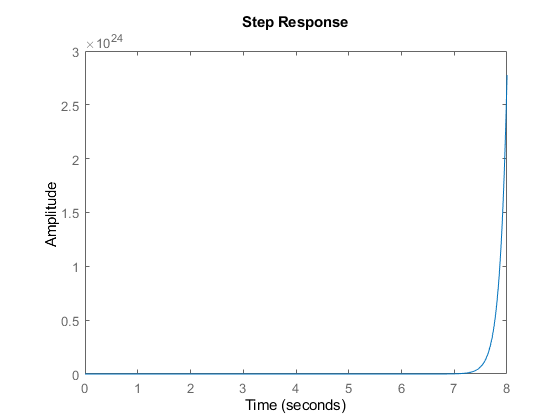

step(sys)

poles = pole(sys)

poles =   -11.5752
   -6.3737
    7.4291
         0


zeros = zero(sys)

zeros = 	1.0e+-14 *

   -0.2159
         0


[num,denum]=ss2tf(A,B,C_angle,D)

num =          0         0   11.1628    0.0000    0.0000


denum =     1.0000   10.5198  -59.5670 -548.0930         0
